clearvars; close all; clc;

# Acoustic impedance ANSYS

2024-05-14, JVsound, J.G. Vermond

## Introduction

The acoustic impedance can be simulated using Finite Element Analysis (FEA). The class feaimport can be used to import pressure results and calculate the acoustic impedance. This acoustic impedance impedance can then be used for SPL calculations using an acoustics.simulation object. The following example shows the workflow.

## Required data

Pre processing: 

- Diaphragm velocity used in the ANSYS simulation, $\dot{x}$:

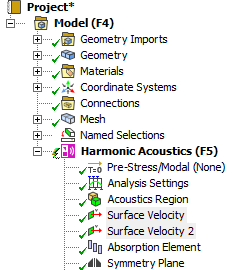

Post processing:

- Average pressure on rear side of diaphragm, $p_{rear}$, as function of frequency.

- Average pressure on front side of diaphragm, $p_{front}$, as function of frequency.

- Optional: pressure at a distance (microphone location), $p_{mix}$, as function of frequency.

The acoustic impedance is defined as:


$$Z_a = \frac{p}{Q}$$


where $Q = \dot{x} \cdot s_D$

## Import data

We need to set values for $\dot{x}$ and $s_D$, in an feaimport object:

% Create feaimport object:
feaimport		= fea.feaimport;

% Assign xdot and sd:
feaimport.xdot	= 1e-3;
feaimport.sd	= 1680e-4;

val				= feaimport.acousticimpedance("pdiarear21inchsub.txt")

val = 1.0e+05 *

  -0.0000 - 0.0127i
  -0.0000 - 0.0128i
  -0.0000 - 0.0129i
  -0.0000 - 0.0130i
  -0.0000 - 0.0132i
  -0.0000 - 0.0133i
  -0.0000 - 0.0134i
  -0.0000 - 0.0135i
  -0.0000 - 0.0137i
  -0.0000 - 0.0138i
